# Signal Distortion in Arbitrary Transmission Line and Termination Impedance

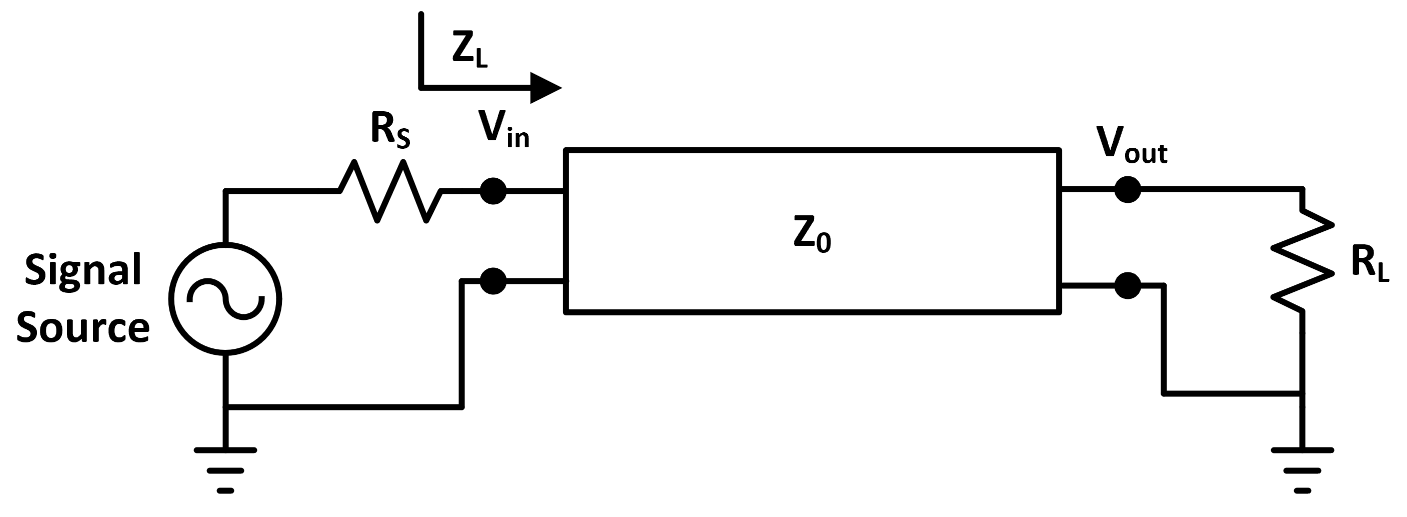

This algorithm output a resulting time domain signal after an arbitrary signal, has passed through an arbitrary transmission line with arbitrary termination impedance. 

Useful for determine the exact amount of signal distorsion after it has passed through a transmission line. 

# Part 1: Transmission line theory explained 

## Defines parameter

This is the first section of the code. Which will explain transmission line theories. **The parameters changed here will not effect simulation result for arbitrary signal simulation **


clear
syms Vp Vo V1;

Vs=2.5*10^8; %speed of light 
Zo=300; %characteristic impedance of the line
Rs=150; %source impedance
RL=15000000;
F=100*10^6; %frequency
Lambda=Vs/F; %wave length
B=2*pi/(Lambda); % beta for e^jBl
n=0.3; % number of wave length 
l=n*Lambda; %length of the transmission line in meters

S11=(RL-Zo)/(RL+Zo); %this is the reflection coefficient at Rl not at the source!!!
S11n=(Rs-Zo)/(Rs+Zo); % reflection coefficient at the sourse

ZL=Zo*(exp(-1i*B*(-l))+S11*exp(1i*B*(-l)))/(exp(-1i*B*(-l))-S11*exp(1i*B*(-l))); %load impedance seen by the source
Vn=S11*Vp; %reflected voltage
Vin=60; %input voltage level


## Transmission line equatons based on steady state theorem

Use fourier transform to convert second derivative in time domain to w^2:


$$\frac{\partial \;V}{\partial \;z^2 }=\textrm{LC}\frac{\partial {\;}^2 V}{\;\partial \;t^2 }\;\Rightarrow \frac{\partial \;V}{\partial \;z^2 }=-\omega {\;}^2 {\textrm{LCV}}_s$$


for the full space time differential equation, the general solution is an arbitrary waveform: ${V\left(z,t\right)=f}_1 \left(t-\frac{z}{v}\right)+f_2 \left(t+\frac{z}{v}\right)=V^+ +V^-$

After taking the fourier transform, we arrives at $\frac{\partial \;V}{\partial \;z^2 }=-\omega {\;}^2 {\textrm{LCV}}_s$ and the solution is $V_s \left(z\right)=V_0^+ e^{-\beta \;z} +V_0^- e^{\beta \;z}$, We can reconstruct the waveform using fourier transform

The steady state solution have a similar form: $V_{\textrm{sT}} \left(z\right)=V^+ e^{-j\beta \;z} +V^- e^{j\beta \;z}$


eqn1 = Vp+Vn==Vo; %wring! Vo forms a standing wave and we can't obtain an overall amplitude like this
eqn2 = Vp*exp(-1i*B*(-l))+S11*Vp*exp(1i*B*(-l))==V1;
eqn3 = V1==ZL/(Rs+ZL)*Vin;
eqns = [eqn1 eqn2 eqn3];

S = solve(eqns,[Vp Vo V1],'ReturnConditions',true);
S.Vo;

abs(vpa(S.Vp)) %V+

$$ans = 52.898802457009642307437463450041$$

Vn=S11*S.Vp;   %V-
abs(vpa(Vn))   %V-

$$ans = 52.896686547229557523440845883854$$

abs(vpa(S.Vo)) %Vo

$$ans = 105.79548900423919983087830933389$$

abs(vpa(S.V1)) %V1

$$ans = 32.692604092451545961634847271837$$

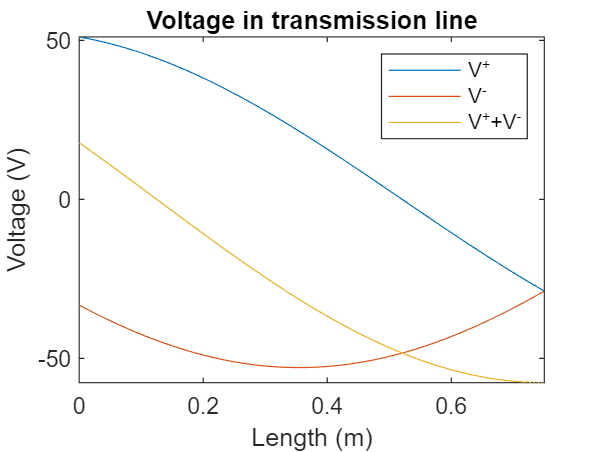


n=70; %number of point
Vp_array=zeros(1,n);
Vn_array=zeros(1,n);
V1_array=zeros(1,n);
x=zeros(1,n);
for z=0:l/n:l
    index=round(z*n/l+1); %index
    Vp_array(1,index)=S.Vp*exp(-1i*B*(z-l)); %incitend wave
    Vn_array(1,index)=Vn*exp(1i*B*(z-l)); %reflected wave
    V1_array(1,index)=Vp_array(index)+Vn_array(index); %sum of incident and reflected
    x(index)=z;
end
figure(1);
fighand=axes(); %fetch than handle of the current figure
plot(fighand,x,real(Vp_array),x,real(Vn_array),x,real(V1_array));

legend(fighand,'V^+','V^-','V^++V^-')
xlabel(fighand,'Length (m)')
ylabel(fighand,'Voltage (V)')
axis(fighand, 'tight')
title(fighand,'Voltage in transmission line') %this plot gives the voltage in transmission line as if you are probing 

%the voltage at each posision on the line

## Transmission line equation using wave composition

The example above used steady state theorem to find the incoming wave and the reflected wave.we will show it here that we can also obtain the same solution by adding up all of the individual components


$$\begin{array}{l}
V_p =V_{\textrm{p1}} +r*V_{\textrm{p1}} +r^{2\;} *V_{\textrm{p1}} \;+\ldotp \ldotp \ldotp \;\;\;\\
V_n =\textrm{S11}*V_p \\
\textrm{where}\;V_p :\textrm{The}\;\textrm{summation}\;\textrm{of}\;\textrm{all}\;\textrm{the}\;\textrm{forward}\;\textrm{traveling}\;\textrm{wave}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;V_{\textrm{p1}} :\textrm{The}\;\textrm{first}\;\textrm{incident}\;\textrm{wave}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;V_n :\;\textrm{The}\;\textrm{summation}\;\textrm{of}\;\textrm{all}\;\textrm{the}\;\textrm{reverse}\;\textrm{traveling}\;\textrm{wave}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;V_{\textrm{n1}} :\textrm{the}\;\textrm{first}\;\textrm{refelcted}\;\textrm{wave}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;r:\Gamma_- \Gamma_+ e^{-\textrm{j2}\beta \;l} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\Gamma_- :\textrm{the}\;\textrm{reflection}\;\textrm{coefficient}\;\textrm{at}\;\textrm{the}\;\textrm{source}\;\left(\textrm{S11n}\right)\\
V_p \;\textrm{can}\;\textrm{be}\;\textrm{expressed}\;\textrm{using}\;\textrm{geometric}\;\textrm{series}:V_{p\;} =\frac{V_{\textrm{p1}} }{1-r}\;\textrm{wich}\;\textrm{means}\;\textrm{the}\;\textrm{resulting}\;\textrm{wave}\;\sum \;\textrm{is}\;\textrm{still}\;a\;\textrm{sinusoid}*a\;\textrm{constant}\\
V_{\textrm{p1}} \;\textrm{can}\;\textrm{be}\;\textrm{easily}\;\textrm{found}\;\textrm{by}\;V_{\textrm{p1}} =V_{\textrm{in}} *\frac{\textrm{Zo}}{\textrm{Rs}+\textrm{Zo}}
\end{array}$$



Vp1c=Vin*(Zo/(Rs+Zo)); %first incident wave
Vpc=Vp1c/(1-S11n*S11*exp(-1i*2*B*l));  % total V+, should equal to V+ calculated above
Vnc=S11*Vpc*exp(-1i*2*B*l);

abs(Vpc) %V+

ans =           52.8988024570096


abs(Vnc) %V-

ans =           52.8966865472295


## Reflected power

Another reason that impedance matched circuit is prefered is because a non matched system will have reflected wave send back to the receiver. boundary can be found by the following equatons:


$$\frac{P_r }{P_i }=\Gamma \;\Gamma {\;}^* \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{P_t }{P_i }=1-\Gamma \;\Gamma {\;}^*$$


peak power: $\frac{V_o *V_o^* }{Z_o^* }\;$

Average power: $\frac{1}{2}*\frac{V_o *V_o^* }{Z_o^* }\;$

Prin=S11n*conj(S11n)

Prin =          0.111111111111111


ptin=1-Prin

ptin =          0.888888888888889



Pri=S11*conj(S11)

Pri =          0.999920003199904


Pti=1-Pri

Pti =       7.99968000959606e-05



plinen=(Vnc)*conj(Vnc)/(conj(Zo));%power in the transmission line reflected wave
pline=Vpc*conj(Vpc)/(conj(Zo));%power in the transmission line incident wave

ptsn=ptin*plinen %power reflected and received by source

ptsn =           8.29054651163217


pts=Pti*pline %power received by load

pts =       0.000746179032909396



vpa(((S.Vp+Vn)*conj(S.Vp+Vn))/RL) %energy consumen by load

$$ans = 0.00074617903290973982921139645907676$$

%vpa(((S.Vp+Vn)*conj(S.Vp+Vn))/Rs) %energy consumed by source


# Part 2: Signal Distortion in Arbitrary Transmission Line and Termination Impedance

## Define parameters

Vs=2.5*10^8; %speed of signal in Transmission line
l=4.502%*Ti*Vs; %length of the transmission line in meters 

l =                      4.502


Zo=50; %characteristic impedance of the line %
Rs=20; %source impedance
RL=1000000; %load imepdance                            %500
S11=(RL-Zo)/(RL+Zo); %this is the reflection coefficient at Rl not at the source!!!
S11n=(Rs-Zo)/(Rs+Zo); % reflection coefficient at the sourse

## Define source arbitrary waveform

In this exaample, single period of a 10Mhz sine wave (repeat every 10us) was used. The fourier series of this pulse was taken and coefficient of each frequency component is stored in the matrix Coeff for reconstruction. fourier series is used as oppose of fourier transform because we have a repeating pulse and it is also easier to extract phase information from fourier series

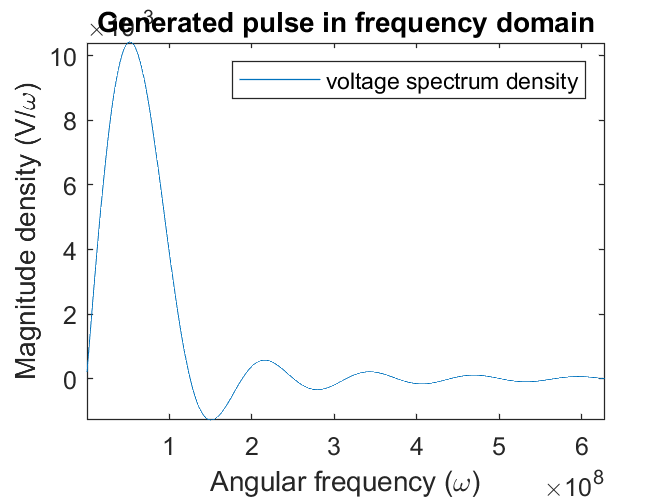


format long g % other wise some index does not work
wp=2*pi*10*10^6; %frequency of the pulse wave form
Tp=2*pi/wp;
Ti=Tp/2;
wo=2*pi*100*10^3; %repetition pulse frequency
To=2*pi/wo;
K=1000; %numbers of points
Coeff=zeros(K,10); % w, an, beta,V+1(first incident wave), V+(at z=0), V-(at z=0) 
index=zeros(K,1);
for k= 1:1:K
    Coeff(k,1)=k*wo;
    if wo*k-wp==0
       %Coeff(k,1)=(-sin(2*Ti*wp)+2*Ti*wp)/(2*wp);
       Coeff(k,2)=2/To*(-sin(Ti*(wp+wo*k))/(wp+wo*k)+Ti); % avoid divide by 0
    else
       Coeff(k,2)=2/To*(-sin(Ti*(wp+wo*k))/(wp+wo*k)+sin(Ti*(wo*k-wp))/(wo*k-wp));
    end
end

figure(2)
plot(Coeff(:,1),Coeff(:,2))

axis('tight')
legend('voltage spectrum density')
xlabel('Angular frequency (\omega)')
ylabel('Magnitude density (V/\omega)')
axis('tight')
title('Generated pulse in frequency domain')

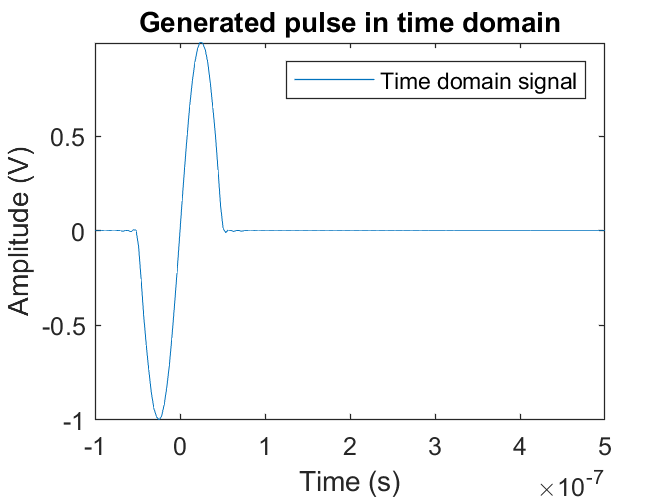


T1=200; % number of sample in the t direction
Tstart=-2*Ti;
Tstop=10*Ti;
x=zeros(1,T1);
Y=zeros(1,T1);
t=linspace(Tstart,Tstop,T1);
for ind=1:1:T1
    
    sum=0;
    for n3=1:1:K
        sum=sum+Coeff(n3,2)*sin(Coeff(n3,1)*t(ind));
    end 
    Y(ind)=sum;
end

figure(3)
plot(t,Y);
axis('tight');
legend('Time domain signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
axis('tight');
title('Generated pulse in time domain');

## How impulse bounce in the transmsision line

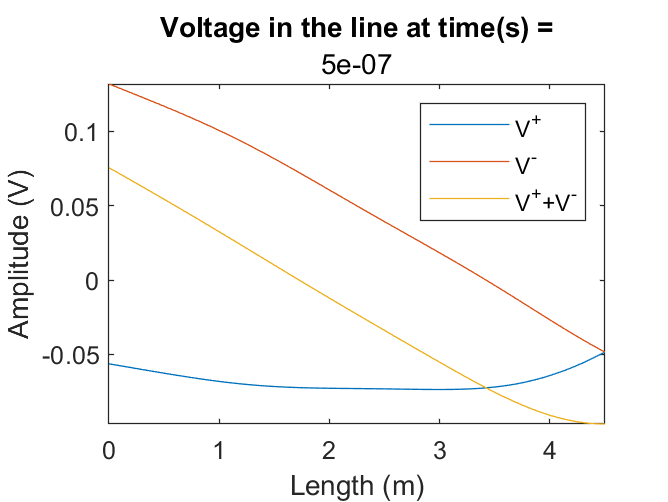


for i=1:1:K
   %Coeff(i,1)= frequency in rad
    Coeff(i,2)= Coeff(i,2);
    Coeff(i,7)= -Coeff(i,2);% an, wave in space f(x) = f(-t) 
    Coeff(i,3)= Coeff(i,1)/Vs; % beta=w/v
    Coeff(i,4)= Coeff(i,7)*(Zo/(Rs+Zo)); % First incoming wave
    Coeff(i,5)= Coeff(i,4)/(1-S11n*S11*exp(-1i*2*Coeff(i,3)*l)); % steady state V+ 
    Coeff(i,6)= Coeff(i,5)*S11*exp(-1i*2*Coeff(i,3)*l); % steady state V-
    Coeff(i,8)= 1/(1-S11n*S11*exp(-1i*2*Coeff(i,3)*l)); %1//()
end

% to plot this, we need do find V+ and V- at any Z.
X1=100; % number of sample in the x direction
%T1=200; % number of sample in the t direction already declared above
z=linspace(0,l,X1);
%t=linspace(-2*Ti,10*Ti,T1); already decleared in the section above
V_array=zeros(3,X1,T1); %3d matrix,two rows of sum of V+ and V-, value at space, value at time


for t1=1:1:T1     % sampling every t position
    for x1=1:1:X1 % sampling every x position
        for k=1:1:K %summation of all the component
            V_array(1,x1,t1)=V_array(1,x1,t1)+Coeff(k,5)*exp(1i*(Coeff(k,1)*t(t1)-Coeff(k,3)*z(x1)))*1i; %V+
            V_array(2,x1,t1)=V_array(2,x1,t1)+Coeff(k,6)*exp(1i*(Coeff(k,1)*t(t1)+Coeff(k,3)*z(x1)))*1i; %V-
        end
        V_array(3,x1,t1)=V_array(1,x1,t1)+V_array(2,x1,t1);
    end
end
figure(5)
space=axes();
time=80;

%This plot plots the voltage in the line at time = Tstop. However, matrix
%V_array contains voltage in the line at all times. Change the variable
%'time' to view all history of voltage in the line.
plot(z,real(V_array(1,:,time)),z,real(V_array(2,:,time)),z,real(V_array(3,:,time)))
axis('tight')
legend('V^+','V^-','V^++V^-')
xlabel('Length (m)')
ylabel('Amplitude (V)')
title('Voltage in the line at time(s) =',Tstop)

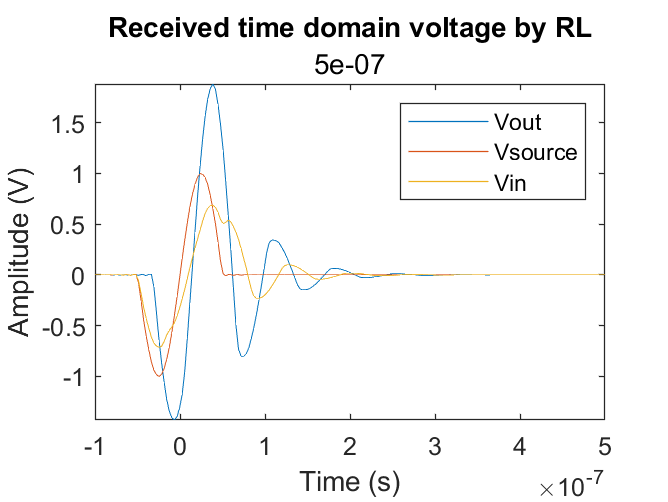


figure(6)
TxRx=axes();
D=zeros(T1,2);
D(:,1)=real(V_array(3,X1,:)); %voltage at load
D(:,2)=real(V_array(3,1,:)); %voltage at source
plot(TxRx,t,D(:,1),t,Y,t,D(:,2))
axis('tight')
xlabel(TxRx,'Time (s)')
legend(TxRx,'Vout','Vsource','Vin')
ylabel('Amplitude (V)')
title('Received time domain voltage by RL',Tstop)

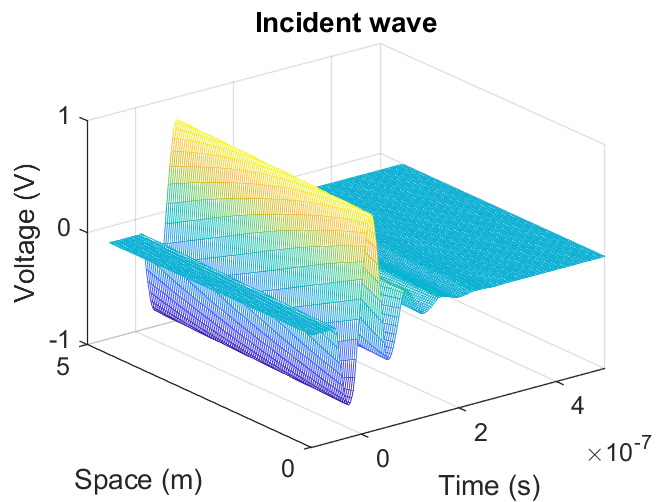


%V+
figure(7)
[Xp,Yp]=meshgrid(t,z);
A=ones(X1,T1);
A(:,:)=real(V_array(1,:,:));
mesh(Xp,Yp,A)
title('Incident wave')
xlabel('Time (s)')
ylabel('Space (m)')
zlabel('Voltage (V)')

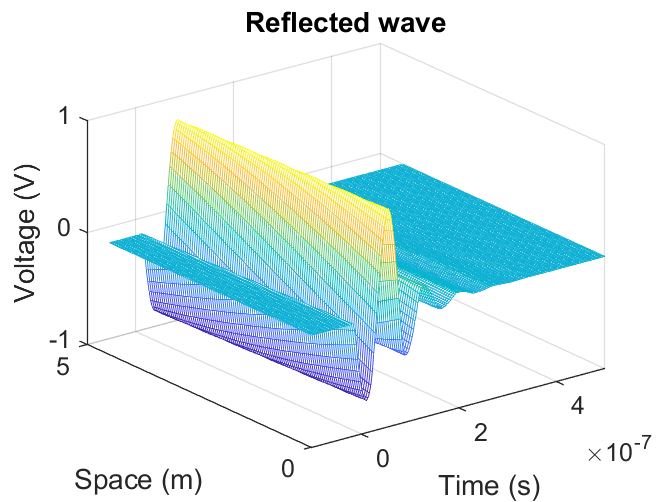



%V-
figure(8)
[Xp,Yp]=meshgrid(t,z);
B=ones(X1,T1);
B(:,:)=real(V_array(2,:,:));
mesh(Xp,Yp,B)
title('Reflected wave')
xlabel('Time (s)')
ylabel('Space (m)')
zlabel('Voltage (V)')

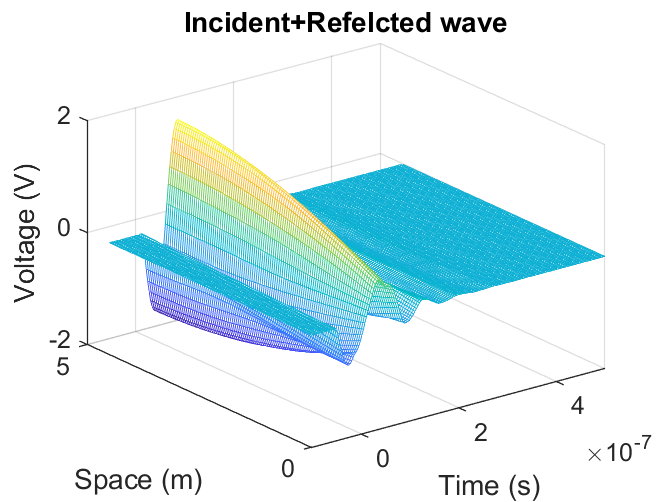


%V++V-
figure(9)
[Xp,Yp]=meshgrid(t,z);
C=ones(X1,T1);
C(:,:)=real(V_array(3,:,:));
mesh(Xp,Yp,C)
title('Incident+Refelcted wave')
xlabel('Time (s)')
ylabel('Space (m)')
zlabel('Voltage (V)')